fs = 44100;
t = 0: 1/fs : 3 - 1/fs;

x = sin(2 * pi * 100 * t) + 0.6 * sin(2 * pi * 200 * t);
noise = 0.5 * randn(size(t));
signal = x + noise;

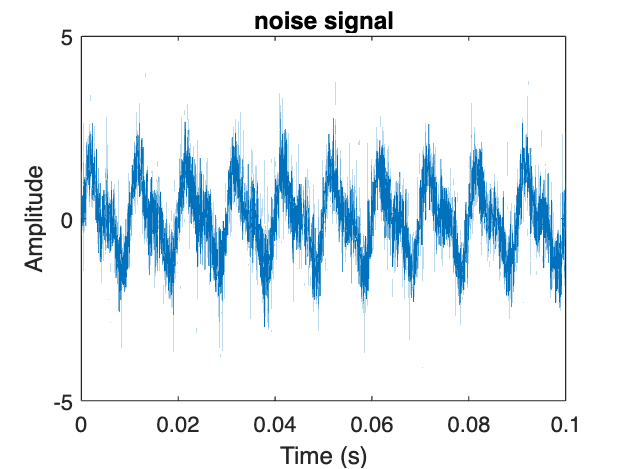

figure;
plot(t, signal)
title('noise signal');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-5, 5]);
xlim([0, 0.1]);

soundsc(signal * 0.1, fs);

soundsc(x * 0.1, fs);

cutoff_freq = 300;
b = fir1(80, cutoff_freq/(fs/2),"low");

filtered_signal = filter(b, 1, signal);
conved_signal = conv(signal, b, "same");

soundsc(filtered_signal*0.1, fs);

soundsc(conved_signal*0.1, fs);

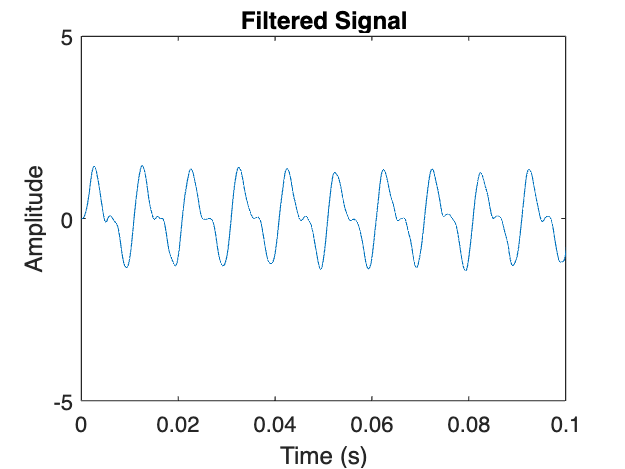

figure;
plot(t, filtered_signal);
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-5, 5]);
xlim([0, 0.1]);

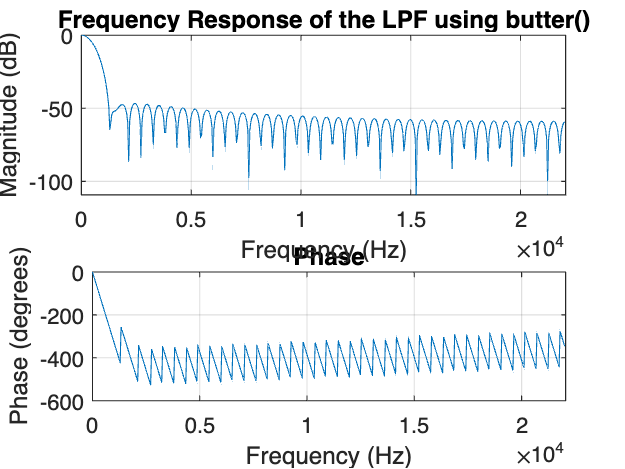

figure;
freqz(b, 1, 512, fs);
title('Frequency Response of the LPF using butter()');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

## Make a FIR and IIR LPF

[b1, a1] = butter(4, cutoff_freq/(fs/2), 'low'); % IIR LPF
signal_IIR = filter(b1, a1, signal);

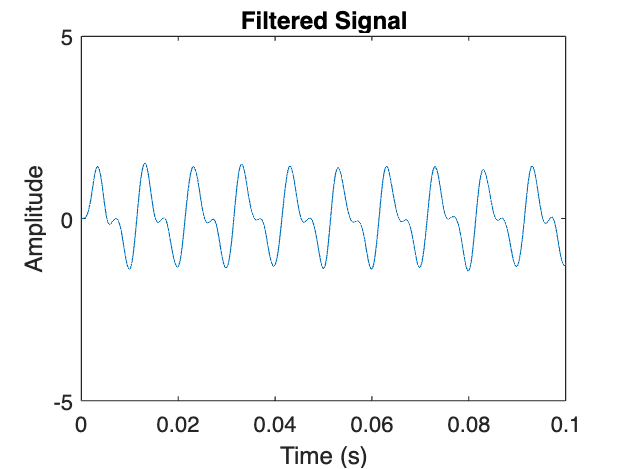

figure;
plot(t, signal_IIR);
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');
ylim([-5, 5]);
xlim([0, 0.1]);

soundsc(signal_IIR*0.1, fs)

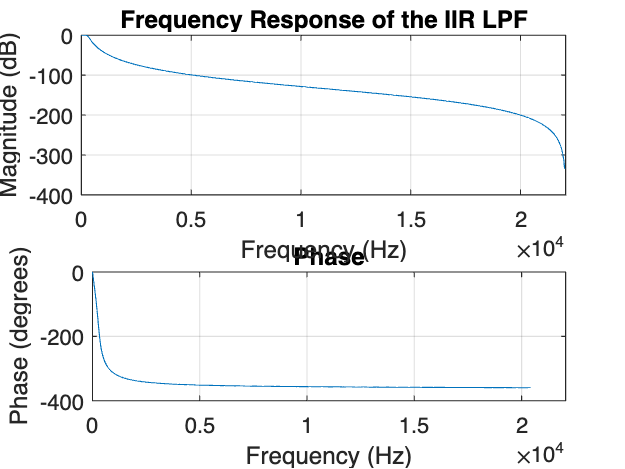

figure;
freqz(b1, a1, 512, fs);
title('Frequency Response of the IIR LPF');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

## Comb filter

delay = 0.05;
gain = 0.5;

% Feedforward comb filter
delay_samples = round(delay * fs);
signal_ff = zeros(size(noise));
signal_ff(1:delay_samples) = noise(1:delay_samples);
for n = delay_samples+1:length(noise)
    signal_ff(n) = noise(n) + gain * noise(n - delay_samples);
end

% Feedback comb filter
signal_fb = zeros(size(noise));
for n = delay_samples+1:length(noise)
    signal_fb(n) = noise(n) + gain * signal_fb(n - delay_samples);
end

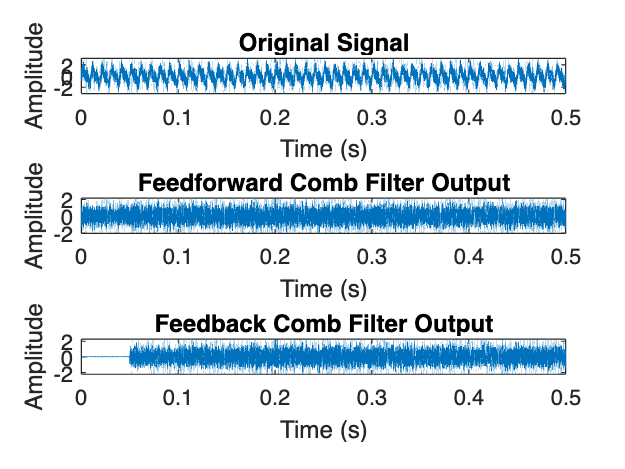

figure;
subplot(3,1,1);
plot(t, signal);
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0, 0.5]);

subplot(3,1,2);
plot(t, signal_ff);
title('Feedforward Comb Filter Output');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0, 0.5]);

subplot(3,1,3);
plot(t, signal_fb);
title('Feedback Comb Filter Output');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0, 0.5]);

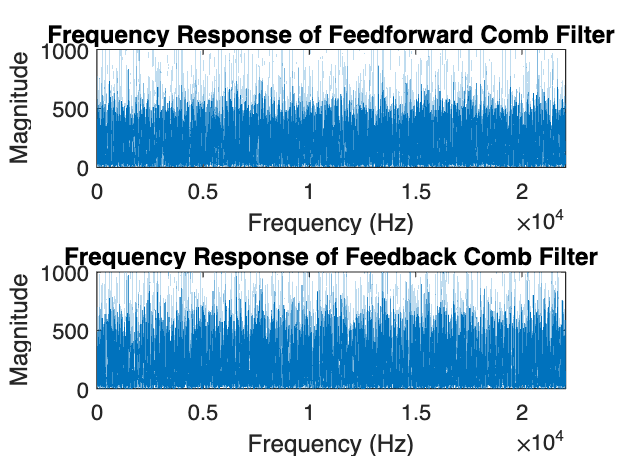

H = fft(noise);
H_mag = abs(H(1:length(t)/2+1));
frequencies = (0:fs/length(t):fs/2);

% Compute frequency response of feedforward comb filter
H_ff = fft(signal_ff);
H_ff_mag = abs(H_ff(1:length(t)/2+1));

% Compute frequency response of feedback comb filter
H_fb = fft(signal_fb);
H_fb_mag = abs(H_fb(1:length(t)/2+1));

% Plot frequency response
figure;
subplot(3,1,);
plot(frequencies, H_ff_mag);
title('Frequency Response of Feedforward Comb Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0, fs/2]);

subplot(3,1,2);
plot(frequencies, H_ff_mag);
title('Frequency Response of Feedforward Comb Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0, fs/2]);

subplot(3,1,3);
plot(frequencies, H_fb_mag);
title('Frequency Response of Feedback Comb Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0, fs/2]);